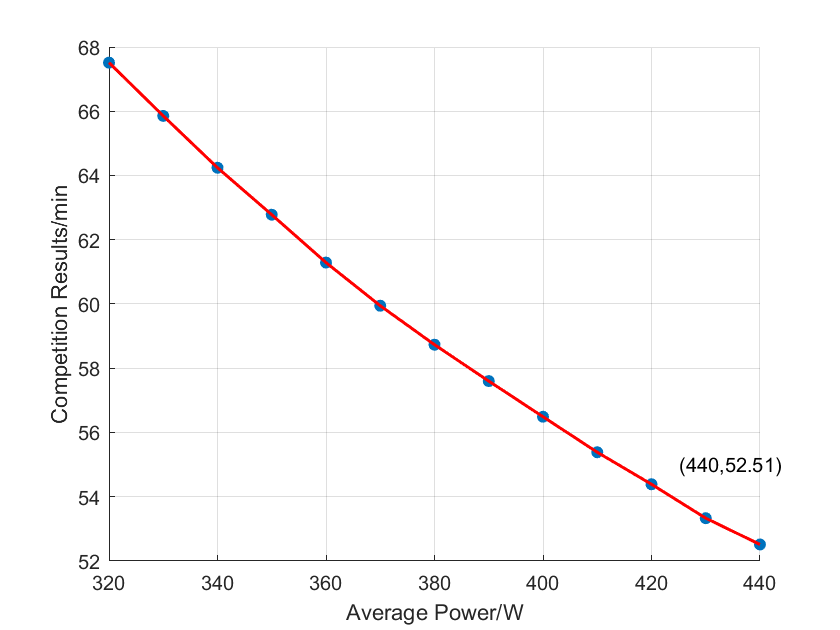

clear y board
Mode.dx = 231;
Mode.rider = 1;
Mode.map=0;
Mode.fluct=10 /100;
Mode.wind = fx/norm([1,1])*(10+10^(-10));
[L direction po]=Map(Mode,6);
switch Mode.dx
    case 231
        x1=log(mmt.z1);y1=log(gp.z1);
        treal=90*60;
        kp0=0.6;
    case 0
        treal=35*60+54+10/60;
        kp0=0.4;
        x1=log(mmt.z1);y1=log(gp.z1);
    case 1
        treal=36*60+05+10/60;
        kp0=0.2;
        x1=log(mmt.z2);y1=log(gp.z2);
end
d=0;
for P = 320:10:510
    d=d+1;
    P2 = P*kp0;
    n = 1;
    [ob]=polyfit(x1,y1,n);
    y = P;
    x=exp((log(y)-ob(2))/ob(1));
    t3 = test1(P2,L,treal,direction,Mode);
    if t3<x
        inlim=1;
    else inlim=0;
    end
    board(d,:)=[P t3 x inlim];
end
n = 1:sum(board(:,4));
figure
scatter(board(n,1),board(n,2)/60*1.3,'filled');hold on
plot(board(n,1),board(n,2)/60*1.3,'r','LineWidth',1.5)
xlabel('Average Power/W' );ylabel('Competition Results/min')
Pi = max(board(n,1));
ob=['(',num2str(Pi),',',num2str(roundn(min(board(n,2)/60*1.3),-2)),')'];
text(max(board(n,1))-15,min(board(n,2)/60*1.3+2.5),ob);
grid on;

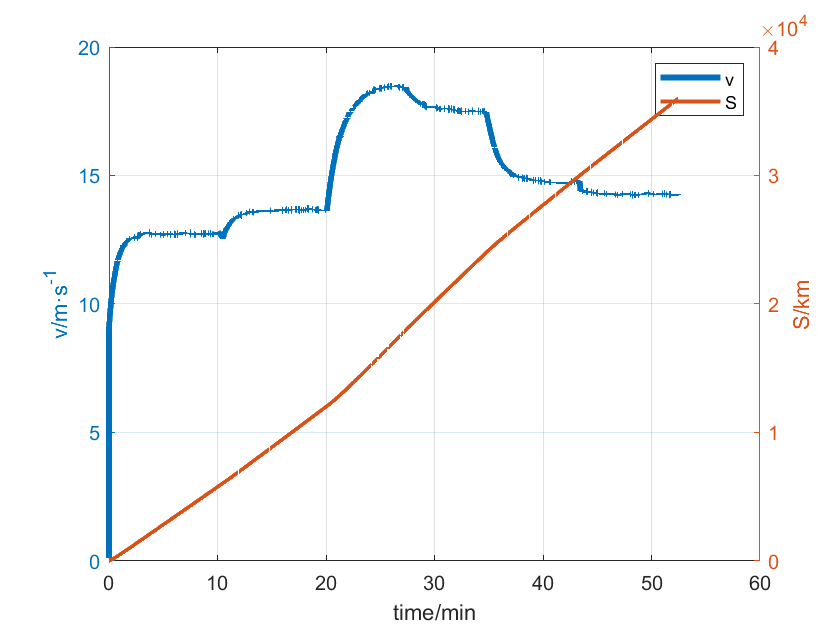


[ans v S t1]= test1(Pi*kp0,L,treal,direction,Mode);
ti=(t1.a:t1.b:t1.end)/60*1.3;
figure;
[Y,H1,H2]=plotyy(ti,v,ti,S);
legend('v','S')
xlabel('time/min');
set(get(Y(1),'ylabel'),'string', 'v/m·s^{-1}');%,'fontsize',16
set(get(Y(2),'ylabel'),'string', 'S/km');
set(H1,'LineWidth',3 );%,'fontsize',16
set(H2,'LineWidth',2 );%,'fontsize',16
grid on;


% figure;
% scatter(ti,v,8,'filled')
% legend('No Wind','Wind','Location','SouthEast')
% xlabel('time/min');ylabel('v/m*s^{-1}')
% set(gca, 'YGrid','on');
% ylim([10, 17]);
% xlim([10,70])

% res1 = res (Mode,I,S,t1,L)

## store

yy0=v;xx0=ti;

yy01=v;xx01=ti;

yy1=v;xx1=ti;

yy25=v;xx25=ti;

yy44=v;xx44=ti;
yy10 = v; xx10 = ti;

## final

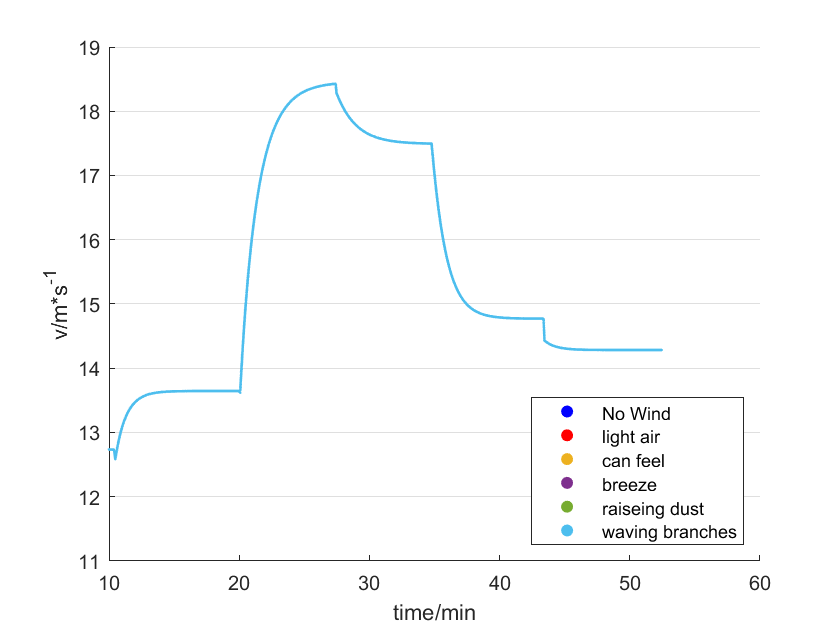

close all
figure;
scatter(xx0,yy0,2,'filled','b');hold on
scatter(xx01,yy01,2,'filled','r');hold on
scatter(xx1,yy1,2,'filled');hold on
% scatter(xx2,yy2,2,'filled')
scatter(xx25,yy25,2,'filled')
scatter(xx44,yy44,2,'filled')
% scatter(xx5,yy5,2,'filled')
scatter(xx10,yy10,2,'filled')

legend('No Wind','light air','can feel','breeze','raiseing dust','waving branches','Location','SouthEast')
xlabel('time/min');ylabel('v/m*s^{-1}')
set(gca, 'YGrid','on');

ylim([11, 19]);
xlim([10,60])

Tend=[max(xx0) max(xx01) max(xx1) max(xx25) max(xx44) max(xx10)]

Tend =    52.4658   52.4658   52.4658   52.4658   52.4658   52.4658
